# Generar y representar usando stem

n=linspace(0,25,26)

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


x1=0*n

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for m=0:10
    x1=x1+(m+1)*[delta(n,2*m)-delta(n,2*m+1)]
end

x1 =      1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     5    -5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     5    -5     6    -6     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     5    -5     6    -6     7    -7     0     0     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     5    -5     6    -6     7    -7     8    -8     0     0     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     5    -5     6    -6     7    -7     8    -8     9    -9     0     0     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     5    -5     6    -6     7    -7     8    -8     9    -9    10   -10     0     0     0     0     0     0


x1 =      1    -1     2    -2     3    -3     4    -4     5    -5     6    -6     7    -7     8    -8     9    -9    10   -10    11   -11     0     0     0     0


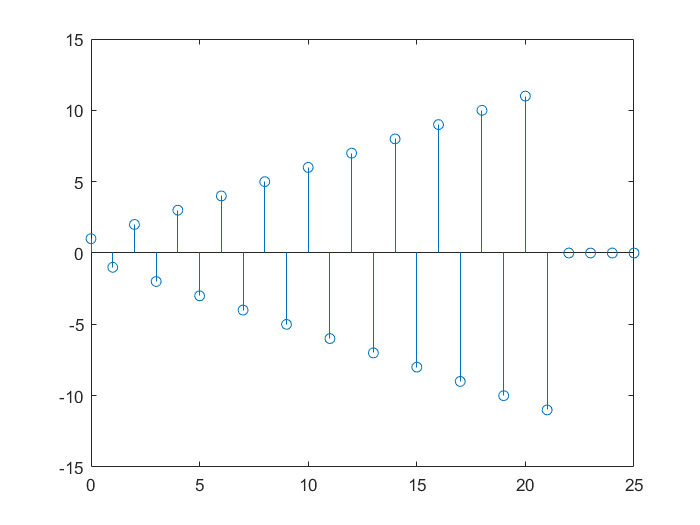

stem(n,x1)

n=-10:10

n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


x2=n.^2.*(escalon(n,-5)-escalon(n,6))+10*delta(n,0)+20*(0.5).^n.*(escalon(n,4)-escalon(n,10))

x2 =          0         0         0         0         0   25.0000   16.0000    9.0000    4.0000    1.0000   10.0000    1.0000    4.0000    9.0000   17.2500   25.6250    0.3125    0.1562    0.0781    0.0391         0


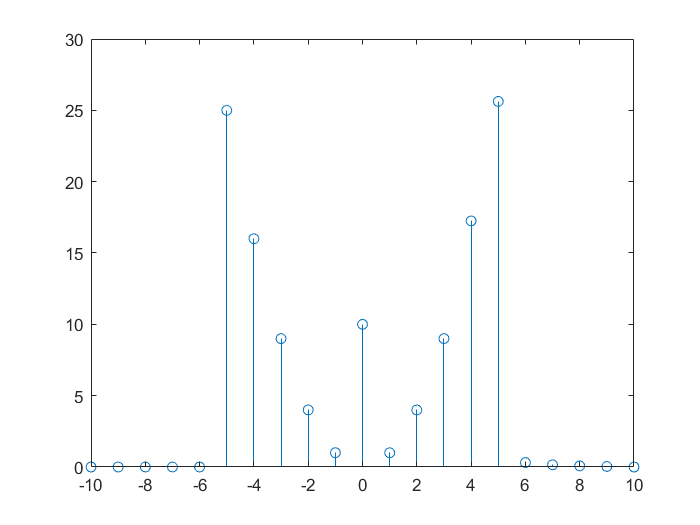

stem(n,x2)

n=0:20

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


x3=(0.9).^n.*cos(0.2*pi*n+(pi/3))

x3 =     0.5000   -0.0941   -0.5420   -0.7131   -0.5994   -0.2952    0.0556    0.3200    0.4211    0.3539    0.1743   -0.0328   -0.1890   -0.2486   -0.2090   -0.1029    0.0194    0.1116    0.1468    0.1234    0.0608


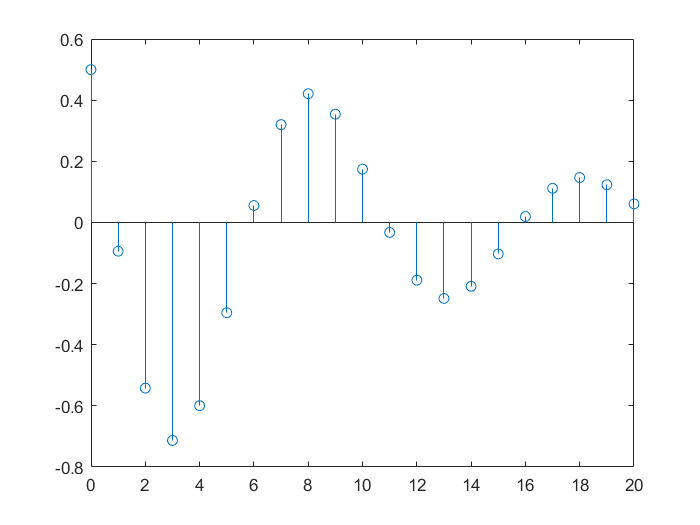

stem(n,x3) 

x5=[2,1,2,3]

x5 =      2     1     2     3


x5p=[x5,x5,x5,x5,x5]

x5p =      2     1     2     3     2     1     2     3     2     1     2     3     2     1     2     3     2     1     2     3


n5=0:19

n5 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


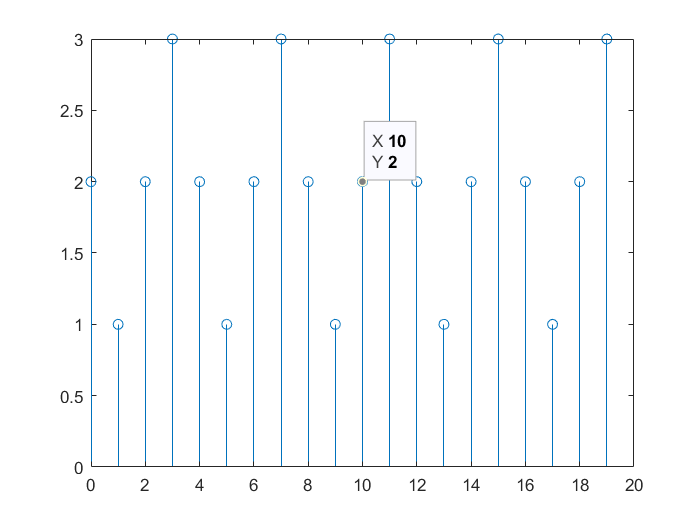

stem(n5,x5p)

x=[1 -2 4 6 -5 8 10]
n=-6:6

# CONVOLUCION

yc=conv(xc,xc);
yteor=0.8.^nc.*(nc+1);
stem(nc,yc(1:Nc))
hold on;
stem(nc, yteor,'r')
